# Testing all images in DB to our dataset in DB1

clear TNM034
clear
clf
clc

## DB1 Testing

files=dir('./DB1/*.jpg');
files =  {files.name};

% Test all files in a dataset against our dataset based on DB1
for file = files
    path = './DB1/' + string(file);
    im = imread(path);
    
%     im = im * 0.7;
%     im = imrotate(im,5,'bilinear','crop');
%     im = imresize(im,0.9);
    
    [id,value] = TNM034(im);
    fprintf('%s, %i, %.16f \n', string(file), id, value);
end

## DB0 Testing

files=dir('./DB1/*.jpg');
files =  {files.name};

% Test all files in a dataset against our dataset based on DB1
j_count = 0;
id_succsess = zeros(1,13)

id_succsess =      0     0     0     0     0     0     0     0     0     0     0     0     0


for j = 0.7:0.05:1.3
    j_count = j_count + 1;
    i = 0;
    for file = files
        i = i+1;
        path = './DB1/' + string(file);
        im = imread(path);
        
        im = im * j;
%       im = imrotate(im,-5,'bilinear','crop');
%         im = imresize(im,0.7);
    
        [id(i), ~] = TNM034(im);
        id(i) = id(i) > 0;
%       fprintf('%s, %i, %.4f \n', string(file), id, value);
    end
    id_succsess(1,j_count) = sum(id);
end

Building dataset:
Creating image matrix
Image: db1_01.jpg 
Image: db1_02.jpg 
Image: db1_03.jpg 
Image: db1_04.jpg 
Image: db1_05.jpg 
Image: db1_06.jpg 
Image: db1_07.jpg 
Image: db1_08.jpg 
Image: db1_09.jpg 
Image: db1_10.jpg 
Image: db1_11.jpg 
Image: db1_12.jpg 
Image: db1_13.jpg 
Image: db1_14.jpg 
Image: db1_15.jpg 
Image: db1_16.jpg 
Creating mean face
Creating weights
Error: cropImage returned no eyes...


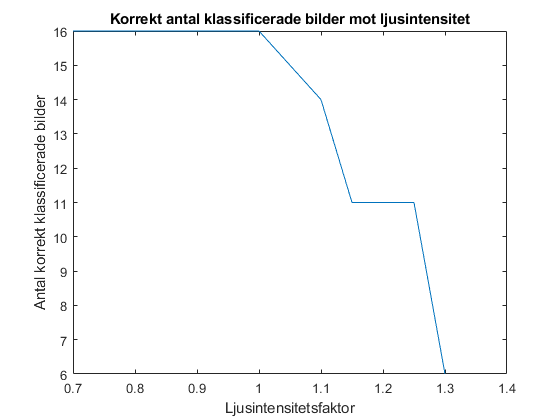

Not enough input arguments.

Error in fontSizeCB

title('Korrekt antal klassificerade bilder mot ljusintensitet')
xlabel('Ljusintensitetsfaktor')
ylabel('Antal korrekt klassificerade bilder')

plot((0.7:0.05:1.3),id_succsess)

## Single file testing

im = imread('./DB1/db1_07.jpg');
% im = imrotate(im,5,'bilinear','crop');
im = im * 1.1;
[id,value] = TNM034(im)

## Misc testing

im = imread('./DB1/db1_08.jpg');
im = im* 1.3;
% im = imrotate(im,20,'bilinear','crop');
% im = cropImage(im*1.1)
% im = whitePatch(im);
% im = normalizeRGBImage(im);
% imshow(im)
% im = faceMask(im);
imshow(im)

